# *Population Models*

The file `population.xlsx` contains the estimated world population (in thousands) every other year from 1950 to 2014.

% To see the plot answers, run this section.
openfig('worldpop1.fig','visible'); % Q1 answer
openfig('worldpop2.fig','visible'); % Q2 answer
openfig('worldpop3.fig','visible'); % Q3 answer
openfig('worldpop4.fig','visible'); % Q4 answer
openfig('worldpop5.fig','visible'); % Q5 & Q6 answer

## 1. Read and plot data

Import the world population data in `population.xlsx` as a table. Plot the data as a function of year with circular markers.

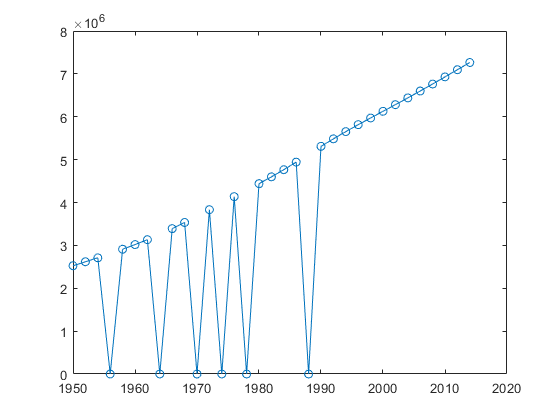

pop_data = readtable("population.xlsx");
plot(pop_data.Year,pop_data.Population,"-o")

## 2. Replace incorrect values with NaN

Note that a population value of 0 is clearly a missing value. Replace the zeros with `NaN `by using` standardizeMissing.` Replot the result.

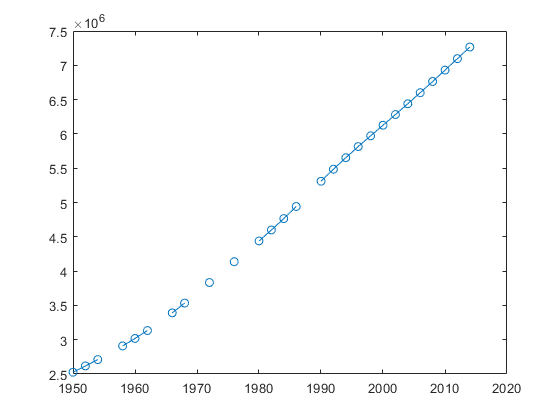

pop_data.Population = standardizeMissing(pop_data.Population,[0 NaN]);
plot(pop_data.Year,pop_data.Population,"-o")

## 3. Fill missing values

Use `fillmissing` to replace the missing values with linearly interpolated values. Replot the result.

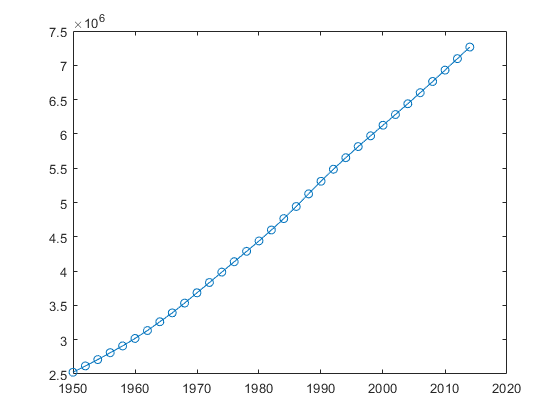

pop_data.Population = fillmissing(pop_data.Population,"linear");
plot(pop_data.Year,pop_data.Population,"-o")

## 4. Fit linear model to the data

Create a column vector of years from 1950 to 2050.

year_col = (1950:2050)';

Fit a linear model(degree of 1) to the data by using `polyfit`. Add the result to the plot of the data.

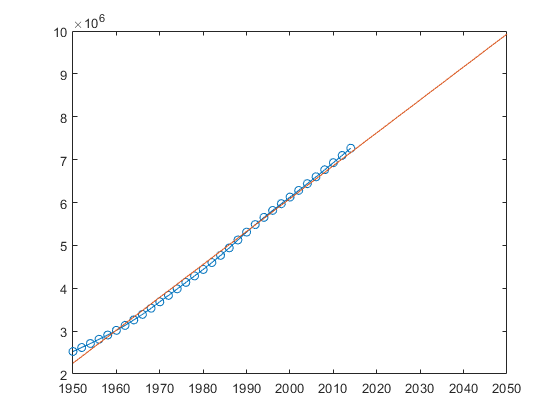

hold on
model = polyfit(pop_data.Year,pop_data.Population,1);
y =polyval(model,year_col);
plot(year_col',y)

## 5. Fit polynomial models of degrees 2 - 5

model = polyfit(pop_data.Year,pop_data.Population,2);
y =polyval(model,year_col);
plot(year_col',y)
model = polyfit(pop_data.Year,pop_data.Population,3);
y =polyval(model,year_col);
plot(year_col',y)
model = polyfit(pop_data.Year,pop_data.Population,4);
y =polyval(model,year_col);
plot(year_col',y)
model = polyfit(pop_data.Year,pop_data.Population,5);
y =polyval(model,year_col);
plot(year_col',y)
hold off

## 6. Polynomial models of degree 1- 5 in 'for' loop

From the Q4 & Q5 results, build a 'for' loop to fit polynomial models of degrees of 1- 5.

figure("Name","Result")
hold on
plot(pop_data.Year,pop_data.Population,"-o")
legend_t = ["Data"];
xlabel("Year")
ylabel("Population [1000s]")

for i=1:5
    model = polyfit(pop_data.Year,pop_data.Population,i);
    y =polyval(model,year_col);
    plot(year_col',y)
    legend_t(i+1) = "Degree "+i;
    
end

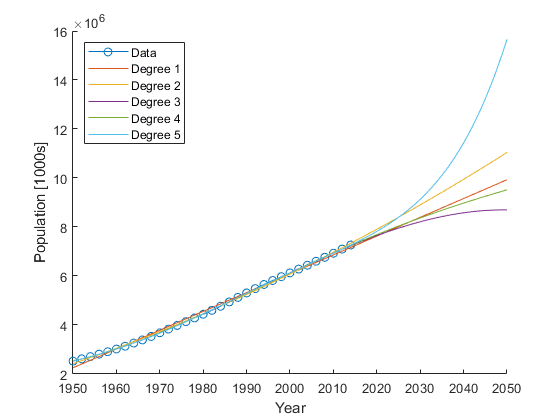


legend(legend_t,"Location","northwest")
hold off